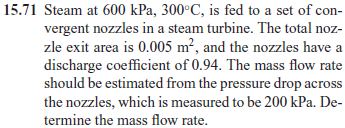

# classes

u = symunit;
steam = ig('Steam');

# stagnation properties

po = 600*u.kPa;
To = c2k(300*u.Celsius);

# critical properties

ps = po*steam.p_po(1);
ps_vpa = vpa(ps)

$$ps\_vpa = 324.53714501775947631756480404874\,\mathrm{kPa}$$

Ts = To*steam.p_po(1);
Ts_vpa = vpa(Ts)

$$Ts\_vpa = 310.01410777821473975235377906756\,K$$

rhos = rewrite(ps/(steam.R*To), 'SI');
rhos_vpa = vpa(rhos)

$$rhos\_vpa = 1.2269430621532785972090894319223\,\frac{\mathrm{kg}}{m^{3}}$$

# outflow properties

pe = po-200*u.kPa; % pe > ps (nozzles are not choked, Me < 1)
syms Me positive;
Me = solve(pe/po ==  steam.p_po(Me));
Me_vpa = vpa(Me)

$$Me\_vpa = 0.80166831803381361542304340463518$$

Te = To*steam.T_To(Me);
Te_vpa = vpa(Te)

$$Te\_vpa = 518.65169447383040476447910066517\,K$$

rhoe = rewrite(pe/(steam.R*Te), 'SI');
rhoe_vpa = vpa(rhoe)

$$rhoe\_vpa = 1.6711386545978825768384609476935\,\frac{\mathrm{kg}}{m^{3}}$$

Ae = 0.005*u.m^2;
Ve = Me*simplify(sqrt(steam.gamma*steam.R*Te));
Ve_vpa = vpa(Ve)

$$Ve\_vpa = 451.80801947439110623873474120053\,\frac{m}{s}$$

# mass flow rate

cD = 0.94;
mdote = cD*rhoe*Ae*Ve;
mdote_vpa = vpa(mdote)

$$mdote\_vpa = 3.5486590752645490532443031907662\,\frac{\mathrm{kg}}{s}$$